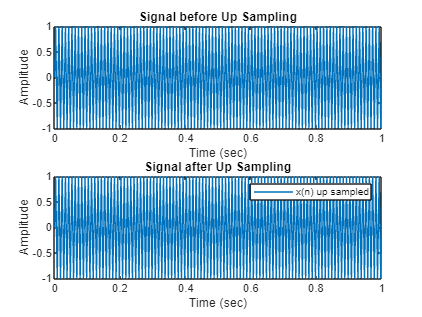

% Define maximum frequency and downsampling factor
Omega_N = 4000; % Maximum frequency in Hz
M = 3; % Downsampling factor

% Choose a sampling rate greater than twice the maximum frequency (Nyquist criterion)
Fs = 2 * Omega_N; % Sampling rate in Hz

% Simulate a continuous-time signal (replace this with your actual signal)
t = 0:0.001:1; % Time vector with 1ms sampling period (adjustable)
x_t = sin(2*pi*1000*t); % Example signal (replace with your desired signal)

% Calculate sampling period from sampling rate
T = 1/Fs;

% Downsample the signal using built-in function (adjust for manual downsampling if needed)
x_downsampled = decimate(x_t, M);

% Plot the original and downsampled signals
figure(1);
plot(t, x_t);
hold on;
stem(t(1:M:end), x_downsampled, 'r'); % Plot downsampled points in red
hold off;
xlabel('Time (s)');
ylabel('Signal Amplitude');
title('Original and Downsampled Signals');
legend('Original Signal', 'Downsampled Signal');
grid on;


% Display information about downsampling
disp(['Original sampling rate: ', num2str(1/T), ' Hz']);

Original sampling rate: 8000 Hz


disp(['Downsampled sampling rate: ', num2str(Fs/M), ' Hz']);

Downsampled sampling rate: 2666.6667 Hz
